## Tutorial 1: A quick start to EXTRACT

In this tutorial, we will work on a simulated calcium imaging movie. Our main goal is to get the first time users started with EXTRACT, though future tutorials will focus on further important hyperparameters. Please refer to Section 2 of the user manual, which is provided both in this Github and as part of the accompanying publication (Inan & Dinc et al., 2024). 

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Part 1: Running EXTRACT

Let us start with a simple cell extraction procedure. The most important parameters discussed in the Section 2 of the user manual are already tuned (though does not differ much from the defaults), but feel free to play around with them!

load(fullfile(whichEXTRACT(),"Learning materials",...
    "Sample data","example.mat")); 
config=[];
config = get_defaults(config); 
config.avg_cell_radius=7;
config.trace_output_option='no_constraint';
config.num_partitions_x=1;
config.num_partitions_y=1; 
config.use_gpu=0; 
config.max_iter = 10; 
config.cellfind_min_snr=0;
config.thresholds.T_min_snr=10;

output=extractor(M,config);

25-Jul-2024 16:26:09: Signal extraction will run on 1 partitions serially... 
25-Jul-2024 16:26:09: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0065 
	 	 	 	 minimum magnitude: 0.0025 
	 	 	 20 cells found after a total of 29 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 20 (0 removed) 
	 	 	 End of iter # 2: # cells: 20 (0 removed) 
	 	 	 End of iter # 3: # cells: 20 (0 removed) 
	 	 	 End of iter # 4: # cells: 20 (0 removed) 
	 	 	 End of iter # 5: # cells: 20 (0 removed) 
	 	 	 End of iter # 6: # cells: 20 (0 removed) 
	 	 	 End of iter # 7: # cells: 20 (0 removed) 
	 	 	 End of iter # 8: # cells: 20 (0 removed) 
	 	 	 End of iter # 9: # cells: 20 (0 removed) 
	 	 	 End of iter # 10: # cells: 20 (0 removed) 
	 	 	 Providing traces with robust regression and no non-ne

### Part 2: Quantifying the cell extraction quality

Fortunately, since this is a simulation movie, we can measure and plot how well we have performed in the cell extraction. Within the 'example.mat' file, we already have cells' ground truth calcium activities, T_ground, and the spatial profiles, S_ground. We first compute the same quantities for the extracted cells:

T_ex = output.temporal_weights';
S_ex = full(output.spatial_weights);
[h,w,k]=size(S_ex);
S_ex=reshape(S_ex,h*w,k);

Note that there are 20 ground truth cells. The code above has also provided us with 20 cells. But, do they match? Did we find all the cells, or did we find some duplicates or spurious ones? To check this, we can use a spatial correlation based function, explained in our publication, that matches the extracted cells to the ground truth:

idx_match = match_sets(S_ex, S_ground,0.8); 
fprintf('Extract found %d out of %d ground truth cells', ...
    size(idx_match,2),size(S_ground,2));

Extract found 20 out of 20 ground truth cells

As can be seen above, EXTRACT found all the cells. 

### Part 3: Visualizing cell extraction outputs

Now, using the visualization functions built-in EXTRACT, let us visualize the cell extraction results:

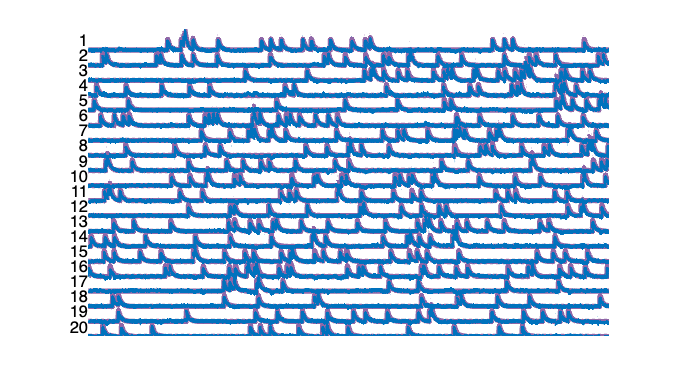

color_extract = [0 0.4470 0.7410];
color_gt      = [144 103 167]./255;
color_l2 = [1,0.5,1];
plot_stacked_traces_double(T_ground(idx_match(2,:),:), ...
    T_ex(idx_match(1,:),:),1,{color_gt,color_extract},[],[],{5,3});

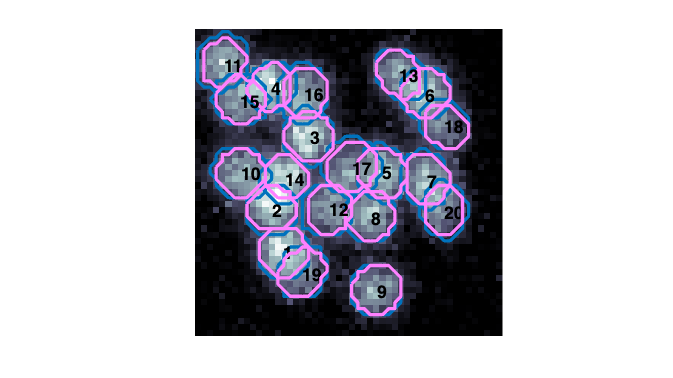


ims_ex = reshape(S_ex,h,w,[]);
ims_g = reshape(S_ground,h,w,[]);
max_im = max(M,[],3);

plot_simulated_cellmap(ims_g, ...
    max_im,ims_ex(:,:,idx_match(1,:)),color_extract,color_l2)

Here, blue corresponds to EXTRACT's outputs, whereas purple corresponds to ground truth values.

### Part 4: Effects of T_min_snr parameter

One of the most important parameters is thresholds.T_min_snr, which need to be adjusted to allow low SNR cells to be picked up. In the code below, we show how very low or very high values of this parameter affect the cell extraction quality.

thr_all = linspace(2,20,10);
precision = zeros(1,size(thr_all,2));
recall    = zeros(1,size(thr_all,2));
for i = 1:size(thr_all,2)
    config.thresholds.T_min_snr=thr_all(i);
    config.verbose = 0;
    output=extractor(M,config);
    S_ex=reshape(full(output.spatial_weights),h*w,[]);
    idx_match = match_sets(S_ex, S_ground,0.8); 
    precision(i) = size(idx_match,2)/size(S_ex,2);
    recall(i) = size(idx_match,2)/size(S_ground,2);
    fprintf('%d finished.\n',i);
end

1 finished.
2 finished.
3 finished.
4 finished.
5 finished.
6 finished.
7 finished.
8 finished.
9 finished.
10 finished.


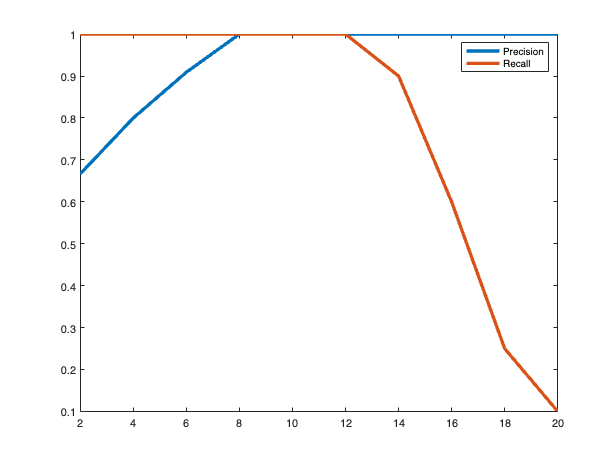



figure
plot(thr_all,precision,'LineWidth',3)
hold on
plot(thr_all,recall,'LineWidth',3)
legend('Precision','Recall')

As can be seen from the code, choosing a very low T_min_snr leads to high recall, but can lead to diminished precision. This is because garbage/duplicate cells cannot be discarded despite having very low SNR values. On the other side, increasing T_min_snr too much can lead to several actual cells being discarded, leading to decreased recall values. Fortunately, the exact ground truth value does not need to be matched, as here flexible choices, i.e. those between 8-12, all provided perfect cell extraction results. 